clear
close all 
clc


data_train = readtable('SYS_IDENT.csv');

data_test  = readtable('Open_Loop.csv');
k = 4700;
Ts = 1; %Sampling time 


u_train = data_train{:,5}; % Input data
u_train = u_train(1:k);
y_train = data_train{:,4}; % Output data
y_train = y_train(1:k);

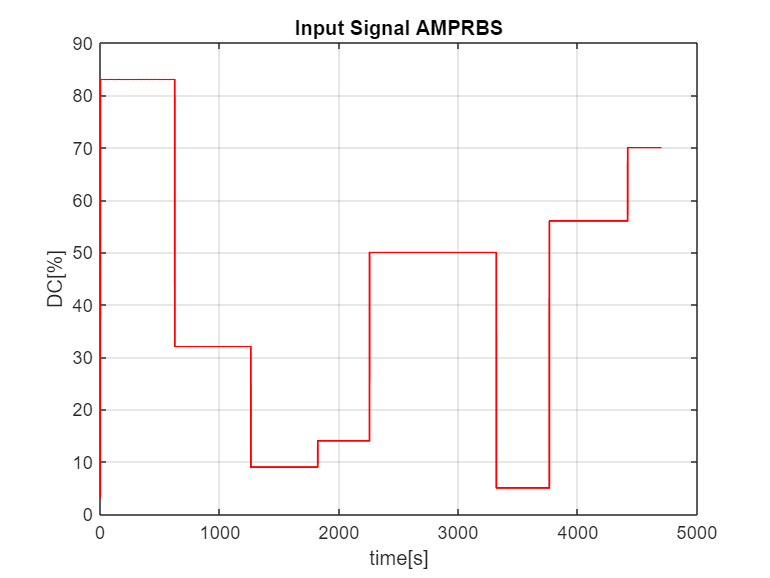

figure(1)
plot(u_train,LineWidth=1,Color="Red")
grid("on")
title("Input Signal AMPRBS")
xlabel("time[s]")
ylabel("DC[%]")


if Ts~=1
    u_train = downsample(u_train,Ts);
    y_train = downsample(y_train,Ts);
end
t_train = 1:Ts:length(y_train);
data_ident_train = iddata(y_train,u_train,Ts,"InputName","u1","OutputName","y1");
data_ident_test = data_ident_train((ceil(length(y_train)/2)+1):length(y_train))

data_ident_test =

Time domain data set with 2350 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


data_ident_train = data_ident_train(1:round(length(y_train)/2))

data_ident_train =

Time domain data set with 2350 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



% Pre Processing Data Test 
% u_test = data_test{:,5}; % Input data
% y_test = data_test{:,4}; % Output data
% 
% if Ts~=1
%     u_test = downsample(u_test,Ts);
%     y_test = downsample(y_test,Ts);
% end
% t_test = 1:Ts:length(y_test);
% data_ident_test = iddata(y_test,u_test,Ts,"InputName","u1","OutputName","y1");

plot(data_ident_test)

Error using iddata/plot
Input was not a valid graphics object.

plot(data_ident_train)

%%IDENTIFICAZIONE NON LINEARE CON NLHW
% select best order by Akaike's information criterion (AIC)
V = arxstruc(data_ident_train,data_ident_test,struc(1:10, 1:10, 1:12));
nn = selstruc(V,'aic')

nn =     10     1     3


nn_1 = selstruc(V,'mdl')

nn_1 =      9     1     3


% idP = idPiecewiseLinear
% mhw1= nlhw(data_ident_train, [9 1 4],idP, [])
%compare(data_ident_train,mhw1);
%compare(data_ident_test,mhw1);
mhw1 = nlhw(data_ident_train, [1 3 1],idSaturation, [])

mhw1 =
Hammerstein-Wiener model with 1 output and 1 input
 Linear transfer function corresponding to the orders nb = 1, nf = 3, nk = 1
 Input nonlinearity: Saturation with linear interval: [-29.6 25.4]
 Output nonlinearity: absent
Sample time: 1 seconds

Status:                                                     
Estimated using NLHW on time domain data "data_ident_train".
Fit to estimation data: 81.95%                              
FPE: 0.3733, MSE: 0.3714


compare(data_ident_train,mhw1)
compare(data_ident_test,mhw1)

% FDT LINEARE DALL'IDENTIFICAZIONE 
mhw1.B
mhw1.F
G = get_plant_fdt(mhw1.F,mhw1.B,Ts)

ans = 1×1 cell array
    {[0 0.0064]}


ans = 1×1 cell array
    {[1 -1.8337 1.7285 -0.8815]}


G =
 
               0.006383
  ----------------------------------
  z^3 - 1.834 z^2 + 1.729 z - 0.8815
 
Sample time: 1 seconds
Discrete-time transfer function.



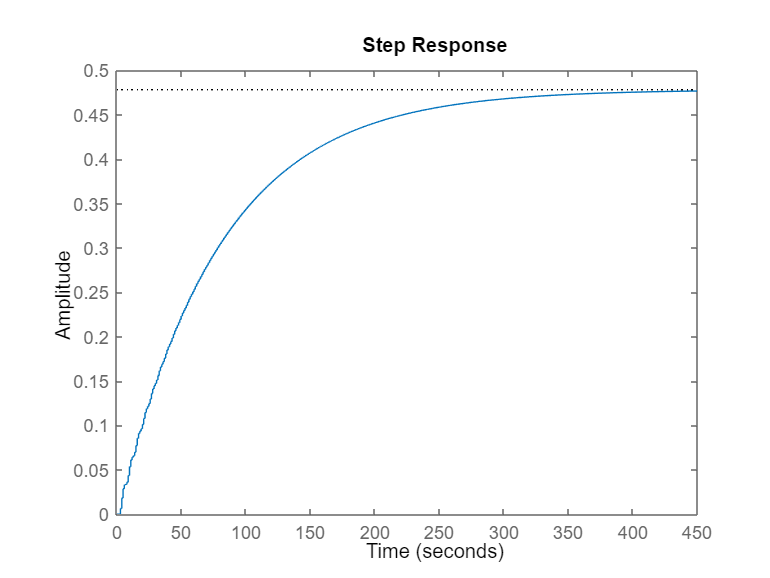

step(G)

G_pid_1 = pidtune(G,'PID')

G_pid_1 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 3, Ki = 0.0757, Kd = 1.48, Ts = 1
 
Sample time: 1 seconds
Discrete-time PID controller in parallel form.



G_s_ident_completo = feedback(G_pid_1*G,1)

G_s_ident_completo =
 
      0.00945 z^2 + 0.0002416 z - 0.009209
  ---------------------------------------------
  z^4 - 2.834 z^3 + 3.572 z^2 - 2.61 z + 0.8723
 
Sample time: 1 seconds
Discrete-time transfer function.



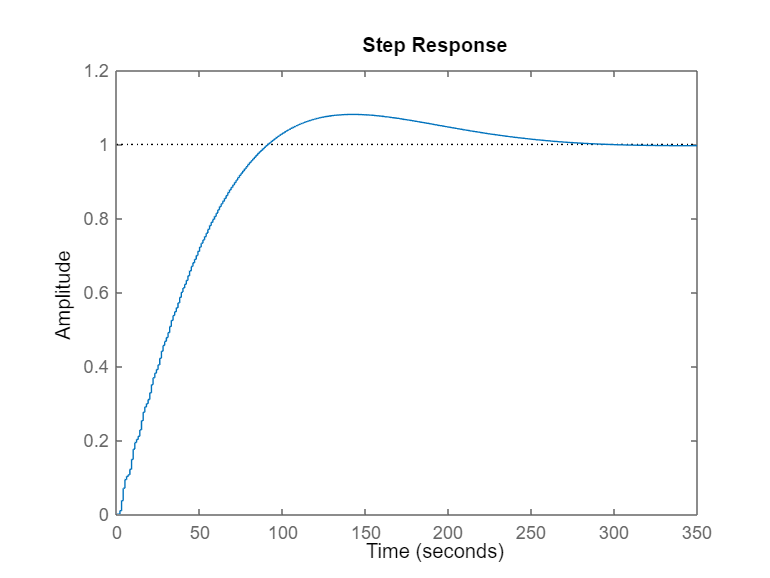

step(G_s_ident_completo)

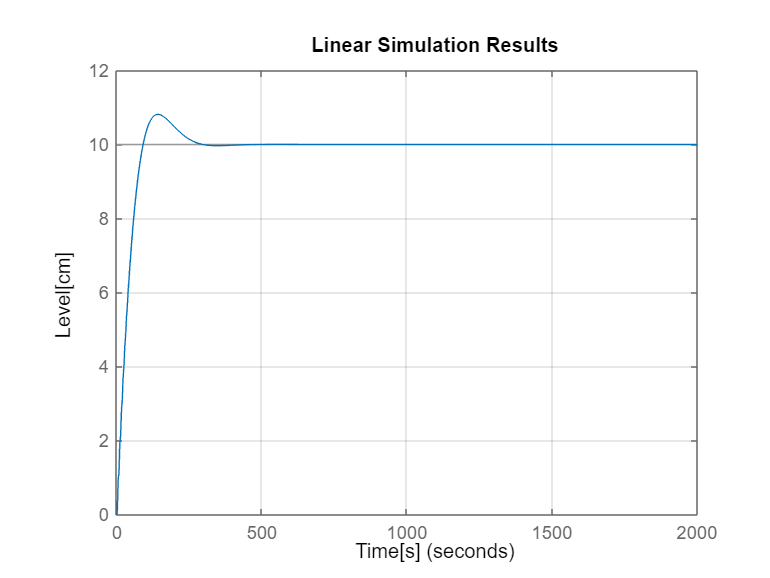

t = 0:2000;
u = 10*ones(length(t),1);
lsim(G_s_ident_completo,u,t)
grid on
ylabel('Level[cm]')
xlabel('Time[s]')

% CONFRONTO CON LA FDT DEL SISTEMA LINEARIZZATO 
s = tf('s');
G_s_lin = (0.0001251)/(s^2+0.03245*s+0.000121)
G_z_lin = c2d(G_s_lin,1,'zoh')
% FDT sistema identificato
G_z_ident = G
G_s_ident = d2c(G_z_ident,'zoh')

% PLOT RISPOSTA A GRADINO 
step(G_s_lin);
hold on 
step(G_s_ident);
legend("G_s_rep","G_s_ide")

% CONFRONTO CON CONTROLLORI PID SU ENTRAMBI I PLANT 
% TEMPO DISCRETO
G_pid_1 = pidtune(G_z_lin,'PID')
G_pid_2= pidtune(G_z_ident,'PID')
G_z_lin_completo = feedback(G_pid_1*G_z_lin,1)
G_z_ident_completo = feedback(G_pid_2*G_z_ident,1)
% TEMPO CONTINUO
G_pid_3 = pidtune(G_s_lin,'PID')
G_pid_4= pidtune(G_s_ident,'PID')
G_s_lin_completo = feedback(G_pid_3*G_s_lin,1)
G_s_ident_completo = feedback(G_pid_4*G_s_ident,1)


close all 
t = 0:2000;
u = 10*ones(length(t),1);
lsim(G_z_lin_completo,u,t) 
hold on 
lsim(G_z_ident_completo,u,t)
hold off
title("TEMPO DISCRETO")
legend("G_z_lin","G_z_ide")

t = 0:0.1:2000;
u = 10*ones(length(t),1);
lsim(G_s_lin_completo,u,t) 
hold on 
lsim(G_s_ident_completo,u,t)
hold off
title("TEMPO CONTINUO")
legend("G_s_lin","G_s_ide")


% STATE SPACE FROM DATA IDENTIFICAZION 
%[A,B,C,D,K] = dssdata(mhw1)
sysTF = tfest(data_ident_train,2,1,0)
compare(data_ident_train,sysTF)
compare(data_ident_test,sysTF)
sysTF = n4sid(data_ident_train,2)
compare(data_ident_train,sysTF)
compare(data_ident_test,sysTF)

% LQR CONTROLLER
G_s = tf(G_z_ident)
[num,den] = tfdata(G_s)
[A,B,C,D] = tf2ss(num{1},den{1})
Q = [400 0; 0 400];
% R = 10
% k = lqr(A,B,Q,R)
% A1=A-B*k;
% sis=ss(A1,B,C,0)

% LQI CONTROLLER 
Q = [0.1 0 0;
    0 0.1 0;
    0 0 0.5];
R = 10
sys = ss(A,B,C,0,1);
ki = lqi(sys,Q,R)
k1 = -ki(1);
k2 = -ki(2);
k3 = ki(3);
A2 = A-B*ki(1:2);
sys_lqi = ss(A2,B,C,0,1)
G_sys_lqi = tf(sys_lqi)
z = tf('z',1);
G_integretor = -ki(3)/(z-1);
G_1 = feedback(G_integretor*G_sys_lqi,1)

t = 0:2000;
u = 10*ones(length(t),1);
lsim(G_1,u,t)
title("LQI CONTROLLER")

[NUM_1,DEN_1] = tfdata(G_sys_lqi);
[NUM_2,DEN_2] = tfdata(G_integretor);
